%% unpack from saved file
imgDir = 'C:\DFiles\Geophysics\Project\Figs_Crosswell';
rayDir = 'C:\DFiles\Geophysics\Inversion\Shuster_labs\Raytracinglab';
% imgDir = 'E:/Geophysics/Project/Crosswell/FWI_2arr';
% rayDir = 'E:\Geophysics\Inversion\Shuster_labs\Raytracinglab';
addpath(rayDir);
% path to save figure
figDir = fullfile(pwd, 'Figures');

fmod1 = 'vp22_pad_smooth.mat';
mod1 = load(fullfile(imgDir, fmod1));
if mod1.fastz 
    vel = mod1.vpGaussBlur';
    vel0 = mod1.vp';
else 
    vel = mod1.vpGaussBlur;
    vel0 = mod1.vp;
end
sln = 1./vel;
refl_ss=(sln-1./vel0)./sln;
[nz, nx] = size(vel); dx = mod1.dx; dz = mod1.dz;
x = (0:nx-1)*dx; z = (0:nz-1)*dz;

% source and receiver geometry sz = 19 m (mid of first layer)
idsrc=21; % mod1.zsrc=(0, 1, 2...)
sx = mod1.xsrc(idsrc); sz = mod1.zsrc(idsrc); gx = mod1.xrec; gz = mod1.zrec; 
g=1:numel(gx);
%% FD params
nbc=40; nt=double(mod1.nt); dt=mod1.dt; t=(0:nt-1)*dt; isFS=false; 
s=ricker(mod1.fc,dt);
% get common shot gather
csg0 =CSG(sx, sz, gx, gz);
csg0 = csg0.getSeis(vel,nbc,dx,nt,dt,mod1.fc,isFS);

Computing shot gather at sx=0.00m sz=20.00m ... 
Elapsed time is 5.461069 seconds.


% get first arrival time
csg0 = csg0.getFirstArrival();

Computing time table sx=0.00m sz=20.00m... 
Elapsed time is 31.742442 seconds.


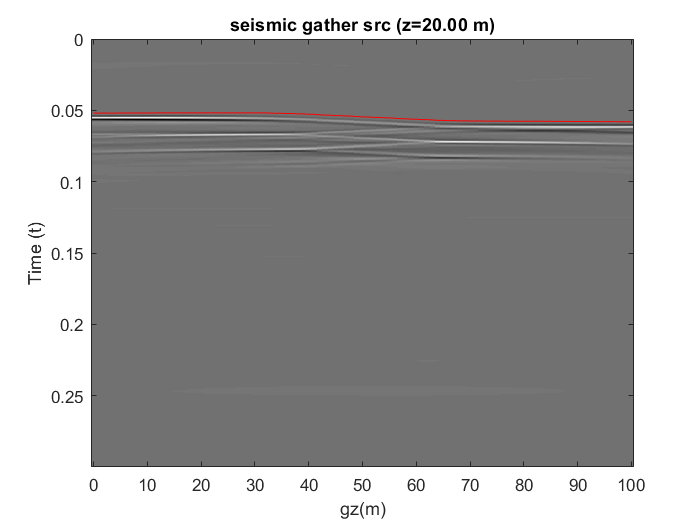

hdCSG = csg0.plotCSG('FA', 'y');
csg0.saveseis(hdCSG, 'gather');

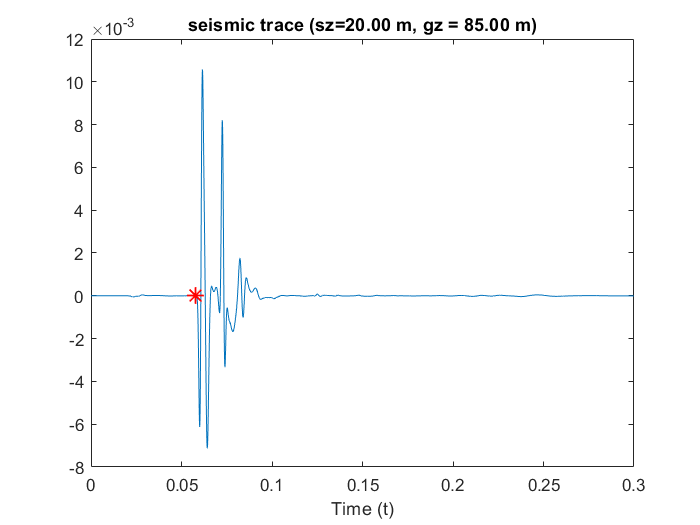

% choose trace at gz = 86 m (mid of bottom layer)
idxTrace = 86; 
hdTr = csg0.plotTrace(idxTrace, 'FA', 'y');
csg0.saveseis(hdTr, 'trace', 'idxTrace', idxTrace);

% refraction/first arrival wavepath
% first arrival is not a perfect ricker; only the first trough is window;
tMute=0.06592;
wp0 = csg0.getWP(idxTrace, 'tEnd', tMute, 'wavetype', 'direct');

Computing wave path (sz=20.00 m, gz = 85.00 m) ... 
Elapsed time is 21.379303 seconds.


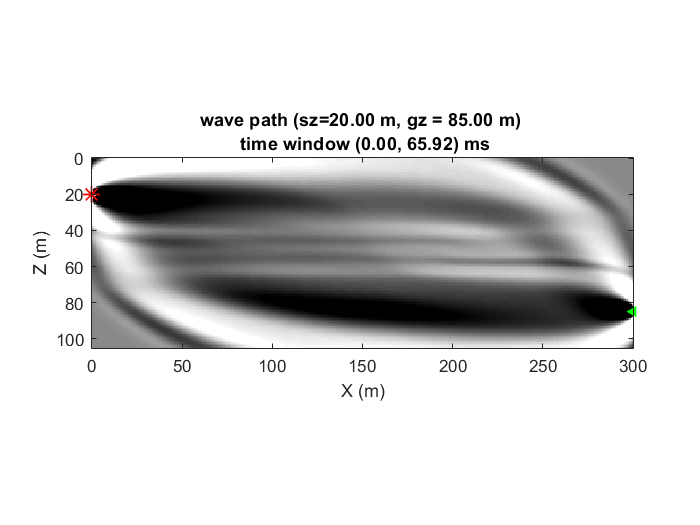

%wp0.plotHist(wp0);
hd_wp0=wp0.plotWP();
wp0.savefig(hd_wp0);

% refle wavepath; a cycle right after the first trough
t1=0.06592; t2=0.0756;
wp1 = csg0.getWP(idxTrace, 'tStart', t1, 'tEnd', t2, 'wavetype', 'refl', 'reflCoeff', refl_ss);

Computing wave path (sz=20.00 m, gz = 85.00 m) ... 
Elapsed time is 44.058516 seconds.


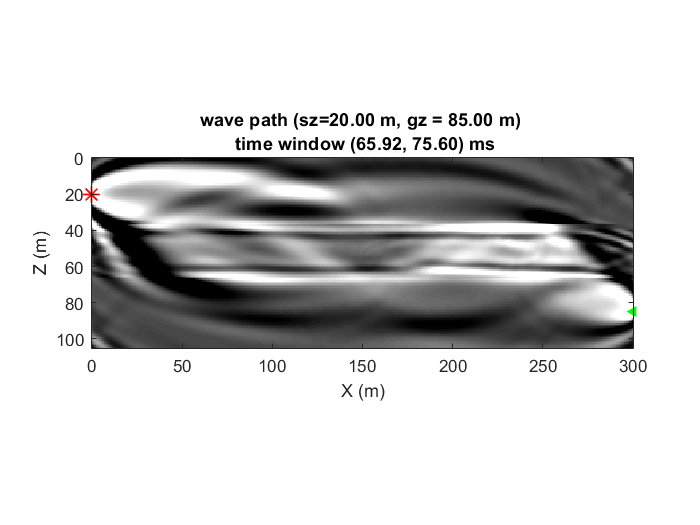

hd_wp1=wp1.plotWP();
wp1.savefig(hd_wp1);

% refle wavepath
t1=0.0756; t2=0.09328;
wp2 = csg0.getWP(idxTrace, 'tStart', t1, 'tEnd', t2, 'wavetype', 'refl', 'reflCoeff', refl_ss);

Computing wave path (sz=20.00 m, gz = 85.00 m) ... 
Elapsed time is 40.056422 seconds.


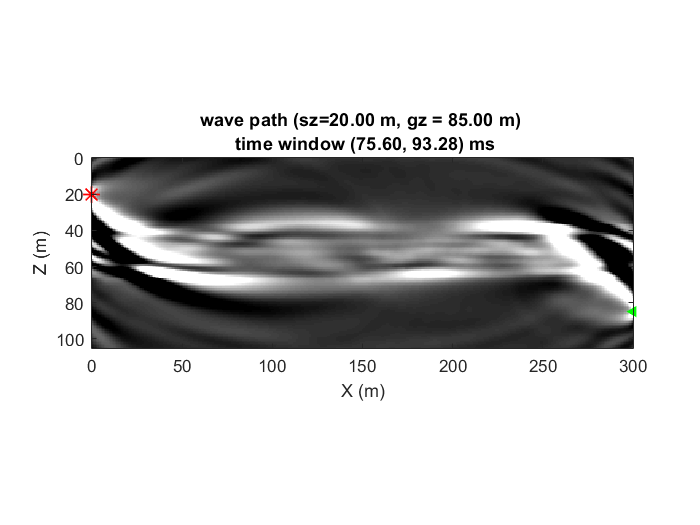

hd_wp2=wp2.plotWP();
wp2.savefig(hd_wp2);